filelist = ["lab4/data/data_01-Apr-2025_16-55-20.mat" %1->30 rads
   "lab4/data/data_01-Apr-2025_17-23-30.mat"       %30->40 rads
    "lab5/data/data_08-Apr-2025_14-30-12.mat"
   "lab5/data/data_08-Apr-2025_14-38-56.mat"
   ]

filelist = 4×1 string array
    "lab4/data/data_01-Apr-2025_16-55-20.mat"
    "lab4/data/data_01-Apr-2025_17-23-30.mat"
    "lab5/data/data_08-Apr-2025_14-30-12.mat"
    "lab5/data/data_08-Apr-2025_14-38-56.mat"


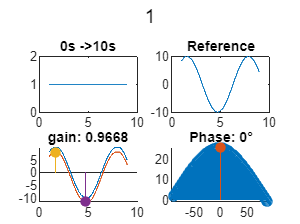

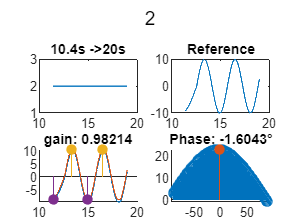

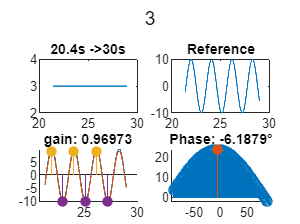

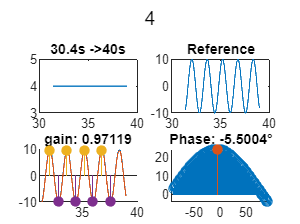

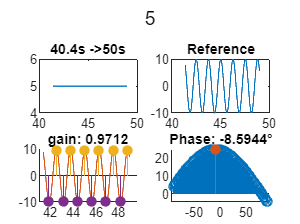

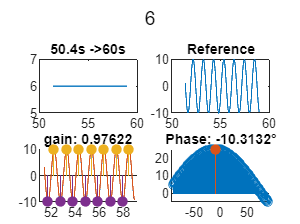

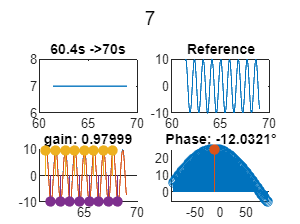

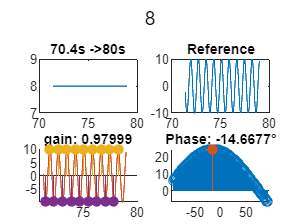



omega_stairs = load("lab4\lab\stairs.mat");
om1 = omega_stairs.x1to30with10s_pause{1};
om2 =  omega_stairs.x30to40with10s_pause{1};
omTSf = {om1; om2; om2; om1};
tstart_d=1;
tend_d=1;
do_plots = true;
bias_angle = 7;
amp = [10 10 2 2 ] ;
tableofData = [];
tableofData2 = [];

for exp_id = 1:4
    filename = filelist(exp_id);
    data = load(filename).data;
    time = data(1,:);
    y = (rad2deg(data(2,:))-bias_angle);
    y_ref = (rad2deg(data(10,:))-bias_angle);

    omeTs=resample(omTSf{exp_id},time);
    om = omeTs.Data;
    slices = sliceTimeSeries(time,om);
    
    for i = 1:size(slices,2)
        if (exp_id ==2 || exp_id ==3)&& i==1

        slices{i}.phase = NaN;
        slices{i}.gain = NaN;
        slices{i}.phase_del = NaN;
            continue
        end
        omega = slices{i}.f;
        focus = slices{i};
    
        t_start_idx = time2index(focus.t_start+tstart_d);
        t_end_idx = time2index(focus.t_end-tend_d);
       
    
        t_focus= time(t_start_idx:t_end_idx);
        om_focus= om(t_start_idx:t_end_idx);
        y_focus= y(t_start_idx:t_end_idx);
        u_focus= y_ref(t_start_idx:t_end_idx);
        if do_plots
            figure
            subplot(2,2,1)
                plot(t_focus,om_focus)
                title(focus.t_start + "s ->" + focus.t_end + "s")
            subplot(2,2,2)
                plot(t_focus,u_focus)
                title("Reference")
            subplot(2,2,[3 4])
        end
        [phase, gain, phase_del] = NewSweepAnalysis(t_focus,u_focus, y_focus, omega, do_plots);
        slices{i}.phase = phase;
        slices{i}.gain = gain;
        slices{i}.phase_del = phase_del;
    end
    
    [freqs,phases, gains, phase_dels] = flatten(slices);
        if do_plots
        figure
        sgtitle("Bode plot exp:" + exp_id)
        subplot(3,1,1)
        scatter(freqs,gains)
        xscale("log")
        title("Gain")
        xlabel("rad/s")
        ylim([0.9, 1.1])

        
        subplot(3,1,2)
        scatter(freqs,rad2deg(phases))
        xscale("log")
        % ylim([0 90])
        title("Phase from Cross Corr")
        xlabel("rad/s")
        ylabel("deg")
        
        
        subplot(3,1,3)
        scatter(freqs,rad2deg(phase_dels))
        xscale("log")
        % ylim([0 90])
        title("Phasefrom Delay")
        xlabel("rad/s")
        ylabel("deg")
    end
    %
    % Save file
    
    if exp_id>2
         tableofData2 = [tableofData2; [freqs; phases; gains]' ];
    else

        tableofData = [tableofData; [freqs; phases; gains]' ];
    end


    % model identification approach
    if exp_id==1
        exp = iddata(y',y_ref',1/500);
    else
        exp_t = iddata(y',y_ref',1/500);
        exp = merge(exp,exp_t);
    end

end



writematrix(tableofData, "lab5/postmotor0expm0", FileType="spreadsheet",WriteMode="overwritesheet")




%get theorethical model params
mu = -1.4479*1.0;
tau =  0.0401;
kp = -21.6;
kd = -0.423;

G = tf([mu],[tau 1 0]);
C = pid(kp,0,kd);
L=G*C;
T = feedback(L,1,-1);
T_d = c2d(T,1/500);
[g_T,p_T,ome_T] = bode(T_d,{1,40});
ang_T = 1*(reshape(p_T(1,1,:),1,[]));
g_T_f = reshape(g_T(1,1,:),1,[]);

zpk(T)


ans =
 
     15.273 (s+51.06)
  ----------------------
  (s^2 + 40.21s + 779.9)
 
Continuous-time zero/pole/gain model.
Model Properties



omegas2 = tableofData2(:,1);
phases2 = tableofData2(:,2);
gains2 = tableofData2(:,3);
% ang_T_id = 1*(reshape(p_T_id(1,1,:),1,[]));
% g_T_f_id = reshape(g_T_id(1,1,:),1,[]);

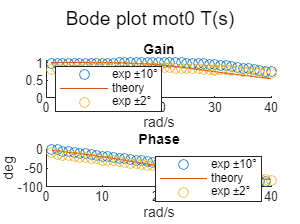

%merge
% PHASE
omegas = tableofData(:,1);
phases = tableofData(:,2);
gains = tableofData(:,3);

figure
sgtitle("Bode plot mot0 T(s)")
subplot(2,1,1)
scatter(omegas,gains)
hold on
plot(ome_T,g_T_f)
scatter(omegas2,gains2)
% yscale("log")
title("Gain")
xlabel("rad/s")
ylim([0 1.1])
legend(["exp ±10°", "theory","exp ±2°"], "Location", 'southwest')
hold  off

subplot(2,1,2)
scatter(omegas,rad2deg(phases))
hold on
plot(ome_T,ang_T)
scatter(omegas2,rad2deg(phases2))
title("Phase")
xlabel("rad/s")
ylabel("deg")
hold  off
legend(["exp ±10°", "theory","exp ±2°"])


function idx = time2index(time)
idx = floor(time/0.002)+1;
end

function [freqs, phases, gain, phase_dels] = flatten(slices)
    freqs = [];
    phases = [];
    gain = [];
    phase_dels = [];
    for i = 1:size(slices,2)
    freqs(i) = slices{i}.f;
    phases(i) = slices{i}.phase;
    gain(i) = slices{i}.gain;
    phase_dels(i) = slices{i}.phase_del;
    end

end